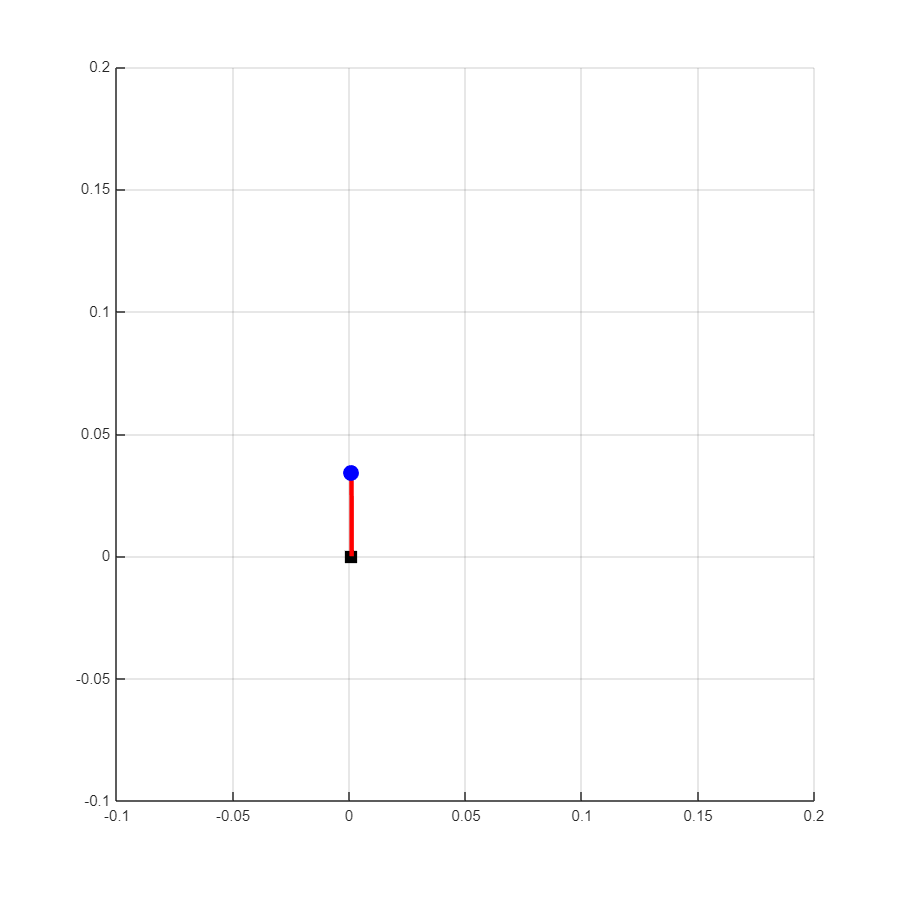

L = l; % pendulum length

figure('Position', [100, 100, 900, 900]);
xlim([-0.1 0.2]);
ylim([-0.1 0.2]);
grid on;
hold on;

% Initial positions
x = x_v(1);
px = x + L*sin(theta_v(1));
py = L*cos(theta_v(1));

% Create graphics objects ONCE
cart = plot(x, 0, 'ks', 'MarkerSize', 10, 'MarkerFaceColor', 'k');
rod  = plot([x px], [0 py], 'r-', 'LineWidth', 3);
mass = plot(px, py, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');

for i = 1:100:length(t_v)
    x = x_v(i);
    px = x + L*sin(theta_v(i));
    py = L*cos(theta_v(i));

    % Update instead of redraw
    set(cart, 'XData', x, 'YData', 0);
    set(rod,  'XData', [x px], 'YData', [0 py]);
    set(mass, 'XData', px, 'YData', py);

    title(sprintf('t = %.2f s', t_v(i)));
    drawnow;
end